image = imread("asthetic_clocktower.jpg") %loading the image 

image = 183×275×3 uint8 array
image(:,:,1) =

    15    15    16    17    18    19    17    18    16    16    15    16    17    17    17    17    22    23    23    23    24    24    25    25    22    23    23    23    24    24    25    25    26    27    26    27    28    29    29    29    27    27    26    27    27    28    26    26    29    29    28    28    28    28    26    26    27    27    26    26    26    26    24    26    27    28    29    30    31    32    31    32    31    29    29    28    28    27    27    28    35    36    35    37    39    41    41    42    45    46    47    49    51    54    54    55    58    59    60    62    62    64    64    65    69    70    69    71    72    73    75    76    83    86    86    87    88    89    90    90    94    95    95    96    97    98    99   100   104   106   105   107   108   109   109   110   109   109   106   104   103   102   101   100   101   101    99    97    96    95    92    91    91    91    91    91    89    89    89

image = image(1:180, 1:272, :) %croping the image

image = 180×272×3 uint8 array
image(:,:,1) =

    15    15    16    17    18    19    17    18    16    16    15    16    17    17    17    17    22    23    23    23    24    24    25    25    22    23    23    23    24    24    25    25    26    27    26    27    28    29    29    29    27    27    26    27    27    28    26    26    29    29    28    28    28    28    26    26    27    27    26    26    26    26    24    26    27    28    29    30    31    32    31    32    31    29    29    28    28    27    27    28    35    36    35    37    39    41    41    42    45    46    47    49    51    54    54    55    58    59    60    62    62    64    64    65    69    70    69    71    72    73    75    76    83    86    86    87    88    89    90    90    94    95    95    96    97    98    99   100   104   106   105   107   108   109   109   110   109   109   106   104   103   102   101   100   101   101    99    97    96    95    92    91    91    91    91    91    89    89    89

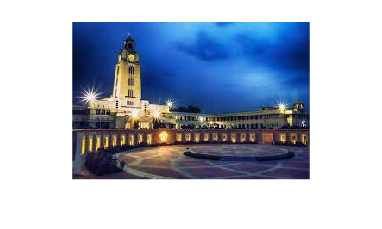

imshow(image)

blockSize = 4 %reducing a 4 by 4 matrix to a single value

blockSize = 4

finalImage = zeros(size(image,1)/blockSize,size(image,2)/blockSize,size(image,3),"uint8") %creating a new zero matrix for the reduced valued of the submatrices to be added to 

finalImage = 45×68×3 uint8 array
finalImage(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   

for i = 1:blockSize:size(image,1)
    for j = 1:blockSize:size(image,2)
        for k = 1:1:size(image,3)
            tSubMx = image(i:i+blockSize-1,j:j+blockSize-1,k);
            finalImage(i,j,k) = ceil(mean(mean(tSubMx)));
        end
    end
end

%avaraging the old values to add it to the the matrix of final image

finalImage = finalImage(1:blockSize:end, 1:blockSize:end, :) %removing the zero i.e skipping from one integer to the other

finalImage = 45×68×3 uint8 array
finalImage(:,:,1) =

    16    17    15    17    22    24    22    24    26    28    27    27    29    28    27    26    27    30    29    29    36    41    46    53    59    63    70    74    86    89    95    98   105   109   106   100    96    90    88    87    80    56    31    26    32    41    54    68    74    76    78    80    80    82    85    85    77    65    52    40    31    23    16    10    12     2     5     7
    13    15    14    15    19    21    19    20    20    22    25    25    31    30    27    25    20    21    26    31    34    39    43    50    56    60    68    72    82    85    91    94   101   104    97    91    81    74    74    73    74    67    55    50    55    66    71    70    74    76    72    74    72    73    76    76    71    61    48    37    26    21    13     8     8     4     4     6
     9    10    12    13    15    16    15    17    15    18    20    24    27    29    27    26    28    17    21    29    30  

imshow(finalImage)